clear

addpath("functions\")

#### Add defect to plate

Model = myModel;
freqs = [1000 2000 4000 16000]; % (Hz)
mesh_size = 3; % 1:finest 9:coarsest

Model = ComsolInterface('Build', Model);

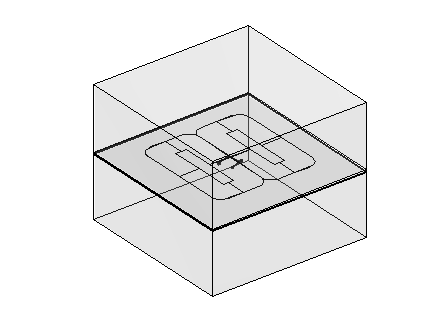


ComsolInterface('AddCircularDefect', Model, -0.004, -0.008, 0.002,    0.0e-3, -1.0e-3)
ComsolInterface('AddCircularDefect', Model,  0.008, -0.004, 0.002,   -0.5e-3, -1.5e-3)
ComsolInterface('AddCircularDefect', Model,  0.004,  0.008, 0.002,   -1.0e-3, -2.0e-3)
ComsolInterface('AddCircularDefect', Model, -0.008,  0.004, 0.002,    0.0e-3, -0.5e-3)
ComsolInterface('AddCircularDefect', Model, -0.008,  0.004, 0.002,   -1.5e-3, -2.0e-3)

figure
ComsolInterface('PlotGeometry', Model)

#### Compute fields

x_s = Model.sensors.positions(1,:);
y_s = Model.sensors.positions(2,:);
z_s = Model.sensors.positions(3,:);

delta_B = zeros(size(Model.sensors.positions,2), 1, length(freqs));
for i = 1:length(freqs)
    tic
    ComsolInterface('Solve', Model, freqs(i), mesh_size, true);
    [Bx, By, Bz] = ComsolInterface('EvaluateField', Model, {'Bx' 'By' 'Bz'}, x_s,y_s,z_s);
    B1 = dot([Bx;By;Bz], Model.sensors.axes);
    fprintf("Solve %g Hz with defects took %.2f seconds\n", freqs(i), toc)

    tic
    ComsolInterface('Solve', Model, freqs(i), mesh_size, false);
    [Bx, By, Bz] = ComsolInterface('EvaluateField', Model, {'Bx' 'By' 'Bz'}, x_s,y_s,z_s);
    B2 = dot([Bx;By;Bz], Model.sensors.axes);
    fprintf("Solve %g Hz without defects took %.2f seconds\n", freqs(i), toc)

    delta_B(:,:,i) = B1 - B2;
end

Solve 1000 Hz with defects took 3052.68 seconds


Solve 1000 Hz without defects took 2468.85 seconds


Solve 2000 Hz with defects took 2573.05 seconds


Solve 2000 Hz without defects took 2589.99 seconds


Solve 4000 Hz with defects took 2574.88 seconds


Solve 4000 Hz without defects took 2559.38 seconds


Solve 16000 Hz with defects took 2176.47 seconds


Solve 16000 Hz without defects took 2237.31 seconds



clear x_s y_s z_s i B1 B2

#### Export sensor data

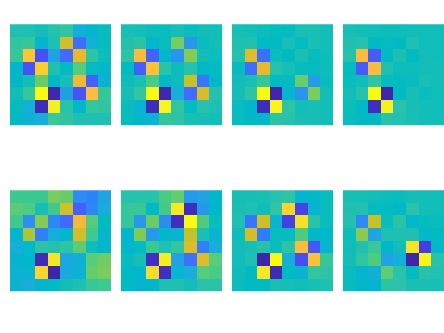

filename = sprintf('data/delta-B_%s.txt', datetime('now','Format','MMdd-HHmm'));
global defects
LoadSaveData(filename, delta_B, freqs, defects)

plot_sensor_data(filename)